The goal is to study the effects of radiation pressure on a 9U satellite with large solar panels.

area = 2;       % m2
ref = 1.5;      % NA
initMass = 10;  % kg
endMass = 8;    % kg
isp = 2000;     % s
g0 = 9.80665;   % m/s2
exhVel = isp * g0;
thrust = 0.001;   % N
mDot = thrust / exhVel;

No propulsion will be needed.

burnOverride = -1;
thrustingThreshold = 1;

Set the orbit's intial conditions. We choose an altitude of 2000 km and a high inclination with adequate RAAN to avoid eclipses.

earthRadius = 6378136.3;    % m
% [sma,ecc,inc,RAAN,aop,true_an] = deal(10000e3+earthRadius, 0.4, 0, 180, 135, -20); % elliptic
% [sma,ecc,inc,RAAN,aop,true_an] = deal(400e3+earthRadius, 0.01, 30, 0, 135, -20); % fairly circular
p = 2000e3+earthRadius; f = 2000e3+earthRadius; sma = (p+f)/2; ecc = (f-p)/(f+p);
[inc,RAAN,aop,true_an] = deal(89, 0, 135, 0);
startDate = juliandate(datetime(2024, 01, 01));

Now choose a simulation length and run it.

tf = 5; tf = tf * 30 * 24 * 3600;
% open_system('propagatorSimple.slx');
tic;
simOutSRP = sim('propagatorSimple.slx');


Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 6.6716s


toc

Elapsed time is 27.540153 seconds.


We extract the data from the simulation. For this, we only care about the position.

tsSatSRP = simOutSRP.yout{1}.Values;
ttSatSRP = timeseries2timetable(tsSatSRP);

To avoid conflicts with the viewer's trajectory interpolation, we retime the timetables manually (this is needed as of R2023b, but may be fixed in future updates).

ttSatSRP = retime(ttSatSRP,'minutely');

To use the same Simulink model for no solar radiation pressure, we just set the area of the satellite to 0.

area = 0;

And now run the simulation again.

tic;
simOutNoSRP = sim('propagatorSimple.slx');


Build Summary

0 of 1 models built (1 models already up to date)
Build duration: 0h 0m 1.6369s


toc

Elapsed time is 7.728428 seconds.


Again extract the data and retime it.

tsSatNoSRP = simOutNoSRP.yout{1}.Values;
ttSatNoSRP = timeseries2timetable(tsSatNoSRP);
ttSatNoSRP = retime(ttSatNoSRP,'minutely');

Raw plot

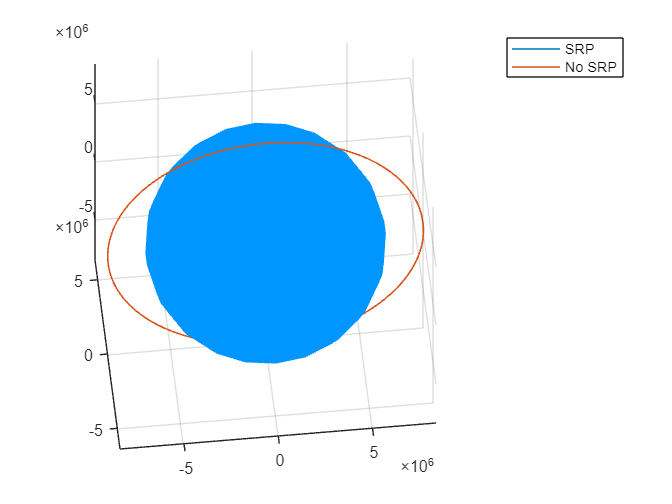

tic
figure
[X,Y,Z] = sphere();
p = surf(X*earthRadius, Y*earthRadius, Z*earthRadius); % plot Earth at the centre
set(p, 'edgecolor', 'none', 'FaceColor', [0,150,255]./255, 'HandleVisibility', 'off')
hold on
plot3(ttSatSRP.Data(:,1), ttSatSRP.Data(:,2), ttSatSRP.Data(:,3), DisplayName='SRP')
plot3(ttSatNoSRP.Data(:,1), ttSatNoSRP.Data(:,2), ttSatNoSRP.Data(:,3), DisplayName='No SRP')
% plot3(ttMoon.Data(:,1), ttMoon.Data(:,2), ttMoon.Data(:,3), DisplayName='Moon')
legend
axis equal
daspect([1 1 1])
view([-6 52])

lim = [-8 8]*1e8;
% xlim(lim)
% ylim(lim)
% zlim(lim)
toc

Elapsed time is 2.142610 seconds.
